# Train Self-Balancing Bicycle Using Reinforcement Learning Agents

Load the parameters of the model into the MATLAB® workspace.

config

Open Simulink Model

model = 'BikeRLAgent';
open_system(model)

## **Create Environment Interface**

Create the observation specification.

numObs = 16;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = "observations";

Create the action specification.

numAct = 2;
actInfo = rlNumericSpec([numAct 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "actions";

Create the environment interface for the walking robot model.

blk = model + "/RL Agent";
env = rlSimulinkEnv(model,blk,obsInfo,actInfo);
env.ResetFcn = @(in) ResetFcn(in, ...
    path_n_points, ...
    path_max_dim, ...
    cvx_hull_n_points, ...
    [min_ref_v, max_ref_v]...
    );

## Create Agent for Training

Build the Critic Network

criticLayerSizes = [400 300];

statePath = [
    featureInputLayer(numObs,'Normalization','none','Name', 'observation')
    fullyConnectedLayer(criticLayerSizes(1), 'Name', 'CriticStateFC1', ... 
            'Weights',2/sqrt(numObs)*(rand(criticLayerSizes(1),numObs)-0.5), ...
            'Bias',2/sqrt(numObs)*(rand(criticLayerSizes(1),1)-0.5))
    reluLayer('Name','CriticStateRelu1')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticStateFC2', ...
            'Weights',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),criticLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(criticLayerSizes(1))*(rand(criticLayerSizes(2),1)-0.5))
    ];
actionPath = [
    featureInputLayer(numAct,'Normalization','none', 'Name', 'action')
    fullyConnectedLayer(criticLayerSizes(2), 'Name', 'CriticActionFC1', ...
            'Weights',2/sqrt(numAct)*(rand(criticLayerSizes(2),numAct)-0.5), ... 
            'Bias',2/sqrt(numAct)*(rand(criticLayerSizes(2),1)-0.5))
    ];
commonPath = [
    additionLayer(2,'Name','add')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(1, 'Name', 'CriticOutput',...
            'Weights',2*5e-3*(rand(1,criticLayerSizes(2))-0.5), ...
            'Bias',2*5e-3*(rand(1,1)-0.5))
    ];

% Connect the layer graph
criticNetwork = layerGraph(statePath);
criticNetwork = addLayers(criticNetwork, actionPath);
criticNetwork = addLayers(criticNetwork, commonPath);
criticNetwork = connectLayers(criticNetwork,'CriticStateFC2','add/in1');
criticNetwork = connectLayers(criticNetwork,'CriticActionFC1','add/in2');

Build the Actor Network

actorLayerSizes = [400 300];
actorNetwork = [
    featureInputLayer(numObs,'Normalization','none','Name','observation')
    fullyConnectedLayer(actorLayerSizes(1), 'Name', 'ActorFC1', ...
            'Weights',2/sqrt(numObs)*(rand(actorLayerSizes(1),numObs)-0.5), ... 
            'Bias',2/sqrt(numObs)*(rand(actorLayerSizes(1),1)-0.5))
    reluLayer('Name', 'ActorRelu1')
    fullyConnectedLayer(actorLayerSizes(2), 'Name', 'ActorFC2', ... 
            'Weights',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),actorLayerSizes(1))-0.5), ... 
            'Bias',2/sqrt(actorLayerSizes(1))*(rand(actorLayerSizes(2),1)-0.5))
    reluLayer('Name', 'ActorRelu2')
    fullyConnectedLayer(numAct, 'Name', 'ActorFC3', ... 
                       'Weights',2*5e-3*(rand(numAct,actorLayerSizes(2))-0.5), ... 
                       'Bias',2*5e-3*(rand(numAct,1)-0.5))                       
    tanhLayer('Name','ActorTanh1')
    ];


%% Specify options for the critic and actor representations using rlOptimizerOptions
criticOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,... 
                                        'GradientThreshold',1,'L2RegularizationFactor',2e-4);
actorOptions = rlOptimizerOptions('Optimizer','adam','LearnRate',1e-3,...
                                       'GradientThreshold',1,'L2RegularizationFactor',1e-5);

%% Create critic and actor representations using specified networks and
% options
critic = rlQValueFunction(criticNetwork,obsInfo,actInfo,'ObservationInputNames','observation','ActionInputNames','action');
actor  = rlContinuousDeterministicActor(actorNetwork,obsInfo,actInfo);

%% Specify DDPG agent options
agentOptions = rlDDPGAgentOptions;
agentOptions.SampleTime = Ts;
agentOptions.DiscountFactor = DiscountFactor;
agentOptions.MiniBatchSize = MiniBatchSize;
agentOptions.ExperienceBufferLength = 1e6;
agentOptions.TargetSmoothFactor = 5e-3;
% agentOptions.NoiseOptions.MeanAttractionConstant = 1;
% agentOptions.NoiseOptions.Variance = 0.1;
agentOptions.ActorOptimizerOptions = actorOptions;
agentOptions.CriticOptimizerOptions = criticOptions;

%% Create agent using specified actor representation, critic representation and agent options
agent = rlDDPGAgent(actor,critic,agentOptions);

## Specify Training Options

maxEpisodes = trainingMaxEpisodes;
maxSteps = floor(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes,...
    MaxStepsPerEpisode=maxSteps,...
    ScoreAveragingWindowLength=50,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=maxEpisodes,...
    SaveAgentCriteria="EpisodeReward",...
    SaveAgentValue=15000, ...
    SaveAgentDirectory = pwd + "\CandidateAgents");

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™. If you do not have Parallel Computing Toolbox software installed, set `UseParallel` to `false`.

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, have each worker send experiences to the parallel pool client (the MATLAB® process which starts the training). DDPG and TD3 agents require workers to send experiences to the client.

trainOpts.UseParallel = false;
% trainOpts.ParallelizationOptions.Mode = "async";
% trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
% trainOpts.ParallelizationOptions.DataToSendFromWorkers = "Experiences";

## Train Agent

Turn on the visualization of the environment during training

set_param(model,'SimMechanicsOpenEditorOnUpdate','off');

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete for each agent. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining `to `true`. Due to randomness in the parallel training, you can expect different training results from the plots that follow. The pretrained agents were trained in parallel using four workers.

do_training = false;
use_pretrained_model = true;
pretrained_model = 'CandidateAgents/Agent769.mat';

agentOptions.ResetExperienceBufferBeforeTraining = not(use_pretrained_model);

if use_pretrained_model
    % Load experiences from pre-trained agent    
    load(pretrained_model,'saved_agent');
    agent = saved_agent;
else
    % Create a fresh new agent
    agent = rlDDPGAgent(actor, critic, agentOptions);
end

if do_training
    % Train the agent
    trainingStats = train(agent, env, trainOpts);
end

## Simulate Trained Agents

Load trained model

set_param(model,'SimMechanicsOpenEditorOnUpdate','off');
load("CandidateAgents/Agent769.mat","agent")

Fix the random generator seed for reproducibility.

rng(5)

To validate the performance of the trained agent, simulate it within the biped robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=maxSteps);
experience = sim(env,agent,simOptions);

Found algebraic loop containing: 
BikeRLAgent/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Dot Product1
BikeRLAgent/env/Blue Bike/Rear Wheel/Tyre model/Camber thrust/Trigonometric Function
BikeRLAgent/env/Config/Solver Configuration/EVAL_KEY/INPUT_4_1_1
BikeRLAgent/env/Config/Solver Configuration/EVAL_KEY/STATE_1
BikeRLAgent/env/Config/Solver Configura

Plot bike perfomance

bike_x = getElement(experience.SimulationInfo.yout, "bike_x").Values.Data

bike_x =    -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


bike_y = getElement(experience.SimulationInfo.yout, "bike_y").Values.Data

bike_y =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



path_x = getElement(experience.SimulationInfo.yout, "path_x").Values.Data

path_x =          0    1.4804    2.7638    3.8162    4.7130    5.5568    6.4502    7.4957    8.7960   10.4536   12.5219   14.8568   17.2652   19.5538   21.5293   22.9985   23.7682   23.6982   22.8609   21.3817   19.3862   16.9998   14.3480   11.5564    8.7361    5.9417    3.2138    0.5927   -1.8812   -4.1676   -6.2259   -8.0157   -9.4967  -10.6285  -11.3707  -11.6827  -11.5243  -10.8551  -10.8551  -11.7841  -12.1758  -12.0912  -11.5917  -10.7384   -9.5925   -8.2152   -6.6677   -5.0113   -3.3070   -1.6162


path_y = getElement(experience.SimulationInfo.yout, "path_y").Values.Data

path_y =          0    0.0228    0.0000   -0.1309   -0.2537   -0.2078    0.1678    1.0336    2.5504    4.8790    8.1065   12.0258   16.3561   20.8166   25.1265   29.0051   32.1717   34.4236   35.8706   36.7010   37.1026   37.2637   37.3721   37.6161   38.1379   38.8969   39.8069   40.7816   41.7346   42.5798   43.2307   43.6012   43.6048   43.1555   42.1667   40.5523   38.2259   35.1014   35.1014   27.3283   20.7933   15.3893   11.0095    7.5467    4.8940    2.9445    1.5912    0.7271    0.2451    0.0384


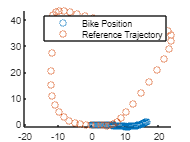


scatter(bike_x, bike_y)
hold on

scatter(path_x, path_y)
legend("Bike Position", "Reference Trajectory")
hold off